# Lab 2

## Kurt Delegard

## PHYS 434 AB

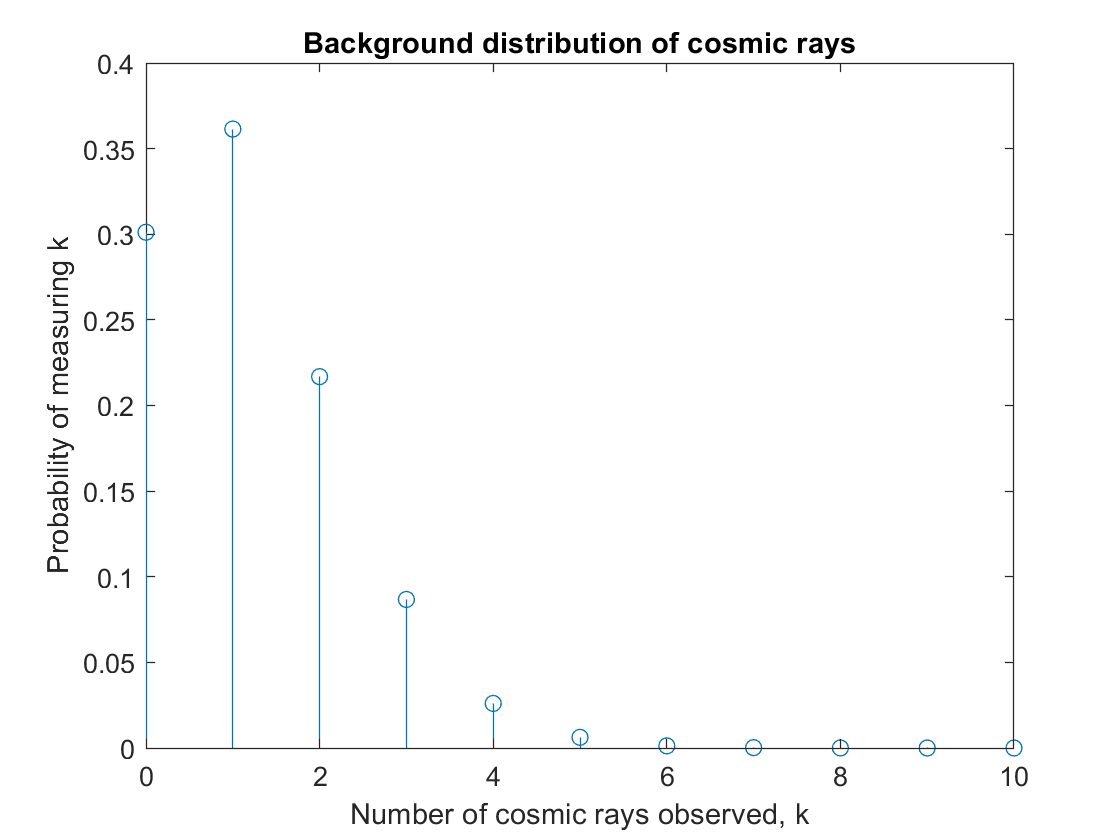

clear;
clf;


%Average cosmic rays per day (background)
X = 1.2;

%Average number of gamma ray emitted by source
Y = 8.0;

pd_bkg = makedist('Poisson', X);
xs = 0:10;
pd_ys = pdf(pd_bkg, xs);
stem(xs, pd_ys);
title('Background distribution of cosmic rays');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

Now we will see how the probability distribution changes as we convolve (sum) the distribution over time:

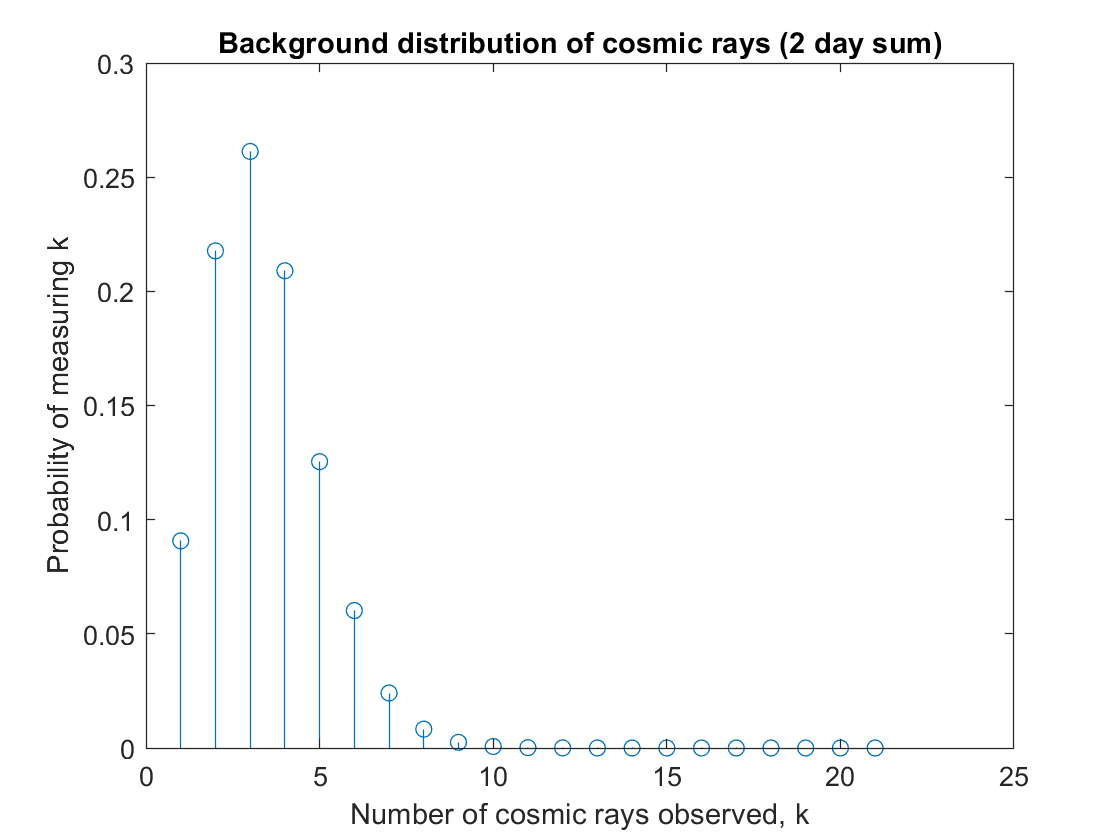

clf;
day_2_pdf = conv(pd_ys, pd_ys);
stem(1:length(day_2_pdf), day_2_pdf);
title('Background distribution of cosmic rays (2 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

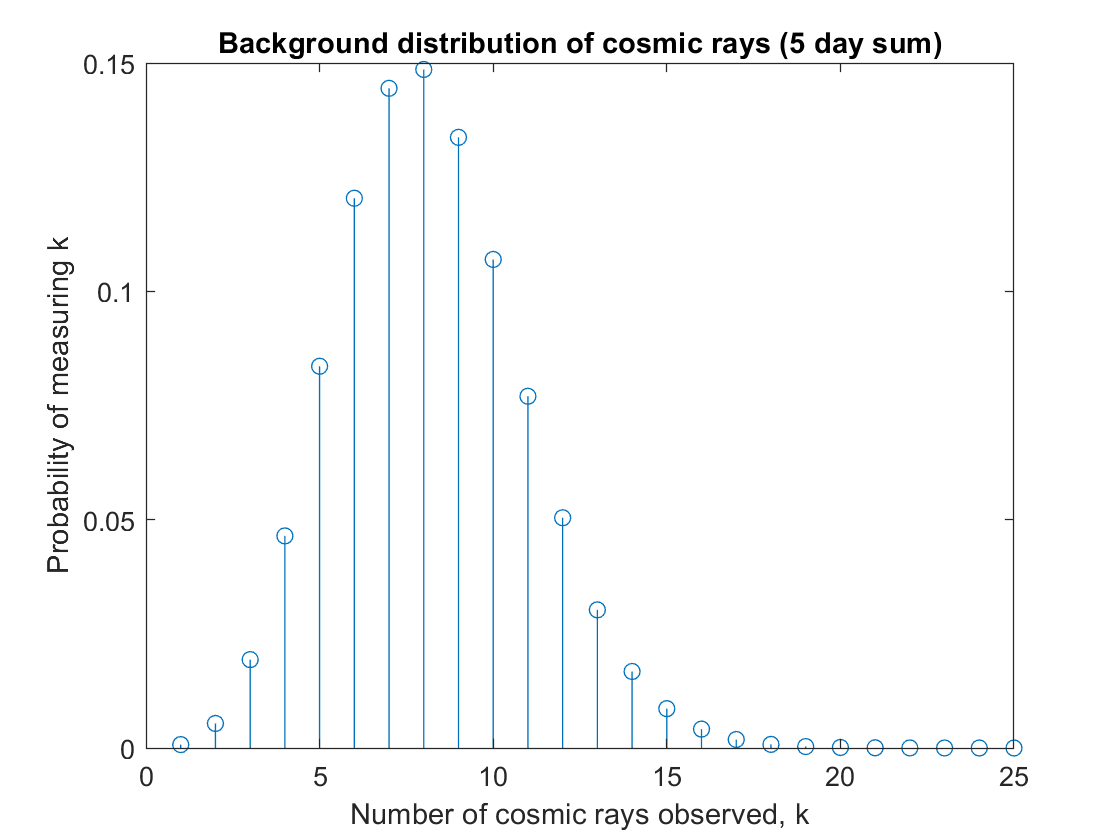

clf;
day_5_pdf = pd_ys;
for ii = 1:5
    day_5_pdf = conv(day_5_pdf, pd_ys);
end

stem(1:length(day_5_pdf), day_5_pdf);
title('Background distribution of cosmic rays (5 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0 25])

We know that as one sums or averages a distribution many times, the convolved distribution will become Gaussian in shape. Is the Poisson distribution - summed over five days - Gaussian at this point?

The logarithm of a normally distributed variable will appear to be parabolic. Let's compare the shape of our convolved distribution with a Gaussian distribution:

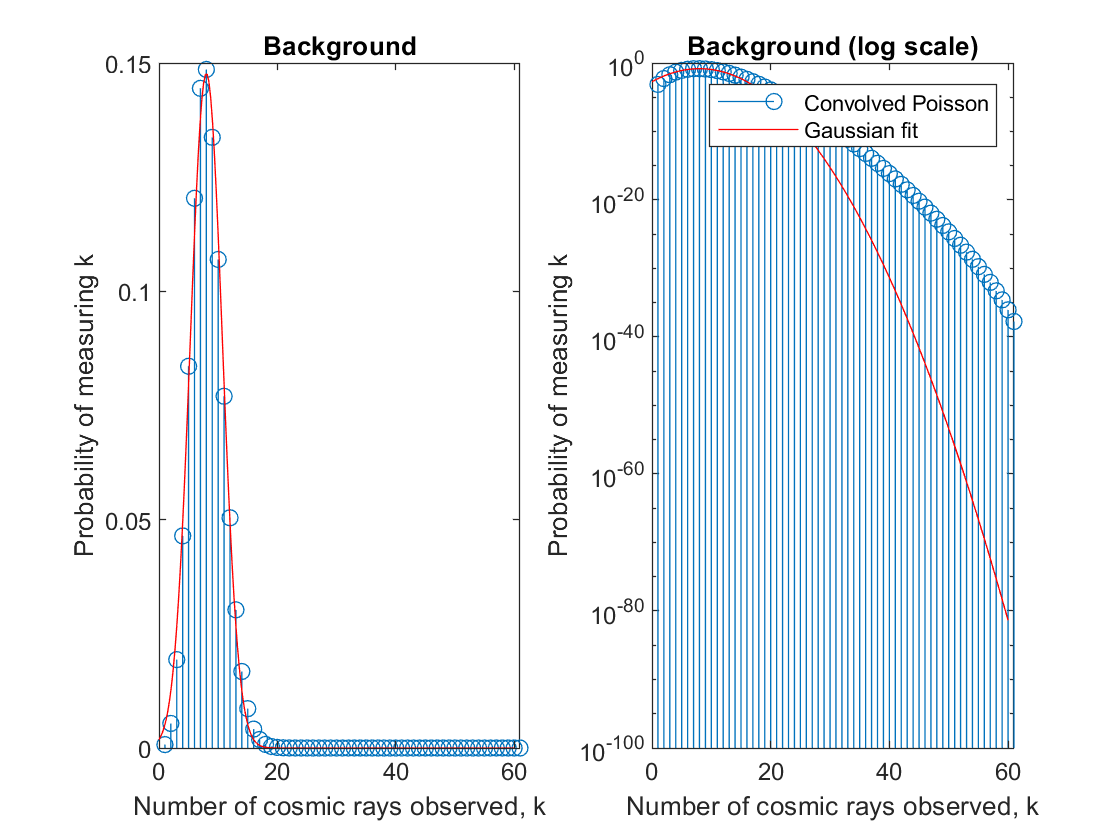

clf;
day_5_pdf = pd_ys;
for ii = 1:5
    day_5_pdf = conv(day_5_pdf, pd_ys);
end

subplot(1, 2, 1);
stem(1:length(day_5_pdf), day_5_pdf), hold on;
normxs = linspace(0, 60, 200);
normys = normpdf(normxs, 8, 2.7);
plot(normxs, normys, 'r-')
title('Background');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

subplot(1, 2, 2);
stem(1:length(day_5_pdf), day_5_pdf), hold on;
plot(normxs, normys, 'r-')
set(gca,'YScale','log')
title('Background (log scale)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
legend('Convolved Poisson', 'Gaussian fit');

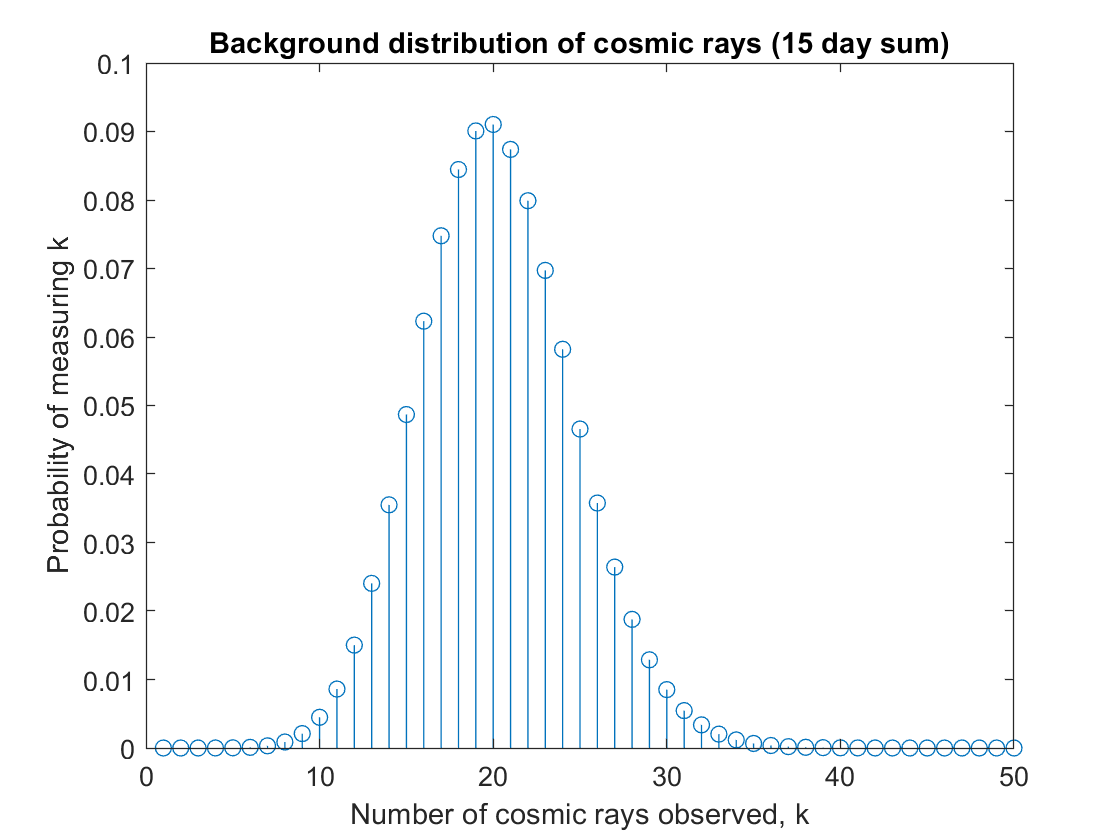

%xlim([0 25])


clf;
day_15_pdf = pd_ys;
for ii = 1:15
    day_15_pdf = conv(day_15_pdf, pd_ys);
end

stem(1:length(day_15_pdf), day_15_pdf);
title('Background distribution of cosmic rays (15 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0, 50]);